N = 2;
unique_matches = {[1; 2]};

num_recursions = 4;
for recursion_number = 1:num_recursions
    N_new = N + 2;
    unique_matches_new = cell(1,factorial(N_new)/power(2,N_new/2)/factorial(N_new/2));
    possible_numbers = 2:N_new;

    for previous_match_set = 1:length(unique_matches)

        for paired_with_one = possible_numbers
            remaining_numbers = possible_numbers(possible_numbers~=paired_with_one);

            new_match_number = (paired_with_one-2)*length(unique_matches)+previous_match_set;

            new_match_matrix = nan(2,N_new/2);
            new_match_matrix(:,1) = [1; paired_with_one];
            
            for rr = 1:2
                for cc = 2:N_new/2
                    new_match_matrix(rr,cc) = remaining_numbers(unique_matches{previous_match_set}(rr,cc-1));
                end
            end
            unique_matches_new{new_match_number} = new_match_matrix;
        end
    end
    unique_matches = unique_matches_new;
    N = N_new;
end

N

N = 10

unique_matches

unique_matches = 1×945 cell array
    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2×5 double}    {2

% Using Unique Matches for Profitability
M = 1;
x = 1;

num_trials = 100;
unique_set_of_pairs_profits = zeros(num_trials,length(unique_matches));
outside_in_set_of_pairs_profits = zeros(num_trials,1);
split_and_match_set_of_pairs_profits = zeros(num_trials,1);
for trial_number = 1:num_trials
    % p_values = sort(rand(1,N));
    p_values = sort(double_stunted_gaussian_inverse_gamma(rand(1,N),1/2,1/20));
    for unique_set_of_pairs_index = 1:length(unique_matches)
        unique_set_of_matches = unique_matches{unique_set_of_pairs_index};
        for pair_index = 1:(N/2)
            p1 = p_values(unique_set_of_matches(1,pair_index));
            p2 = p_values(unique_set_of_matches(2,pair_index));
            peer_bet = peer_to_peer(p1,p2,M,x);
            unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) = unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) + peer_bet.profit;
        end
    end

    for pair_index = 1:(N/2)
        p1 = p_values(pair_index);
        p2 = p_values(N+1-pair_index);
        peer_bet = peer_to_peer(p1,p2,M,x);
        outside_in_set_of_pairs_profits(trial_number) = unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) + peer_bet.profit;

        p1 = p_values(pair_index);
        p2 = p_values(pair_index+N/2);
        peer_bet = peer_to_peer(p1,p2,M,x);
        split_and_match_set_of_pairs_profits(trial_number) = unique_set_of_pairs_profits(trial_number,unique_set_of_pairs_index) + peer_bet.profit;
    end
end

sum(unique_set_of_pairs_profits)

ans =     4.8388    6.8023    6.7945    6.3721    8.3305    8.3154    6.3729    9.8236    9.8164    8.3274    9.8197    9.8074    8.3060    9.8062    9.8011    6.3345    8.2979    8.2901    7.8672    9.8256    9.8105    7.8704   11.3211   11.3139    9.8362   11.3285   11.3162    9.8182   11.3183   11.3132    6.3335    8.2970    8.2892    9.3573   11.3118   11.2905    9.3597   12.8074   12.7938   11.3255   12.8186   12.7961   11.3075   12.8085   12.7995    7.8676    9.8260    9.8109    9.3587   11.3132


[~,best_strategy_indeces] = max(unique_set_of_pairs_profits,[],2);
best_strategy_indeces = unique(best_strategy_indeces)

best_strategy_indeces =    473
   474
   477
   479
   480
   510
   518
   519
   522
   524


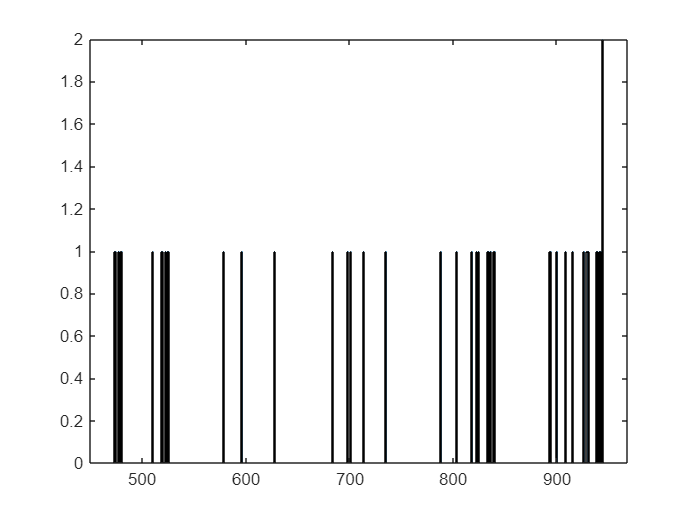


histogram(best_strategy_indeces,'BinWidth',1)


max(unique_set_of_pairs_profits,[],2)

ans =     0.2300
    0.1839
    0.3038
    0.2047
    0.1626
    0.2787
    0.1958
    0.2735
    0.2834
    0.1762


outside_in_set_of_pairs_profits

outside_in_set_of_pairs_profits =     0.2328
    0.1862
    0.3284
    0.2104
    0.1681
    0.2859
    0.2092
    0.2819
    0.2864
    0.1784


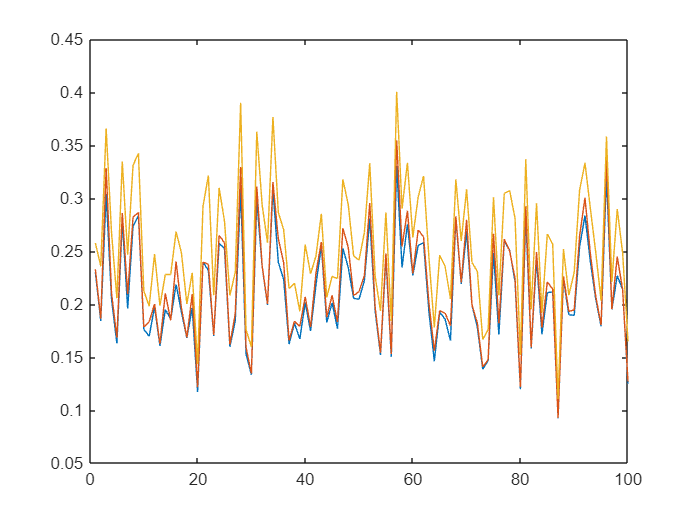


plot(1:100,max(unique_set_of_pairs_profits,[],2))
hold on
plot(1:100,outside_in_set_of_pairs_profits)
plot(1:100,split_and_match_set_of_pairs_profits)